# 本段代码用来计算改变测量方向对类W态集体导引的影响

以不等式SetⅠ2为例，不等式的值是随测量方向周期性变化

集体导引能力最大为类W态，因此以类W为例

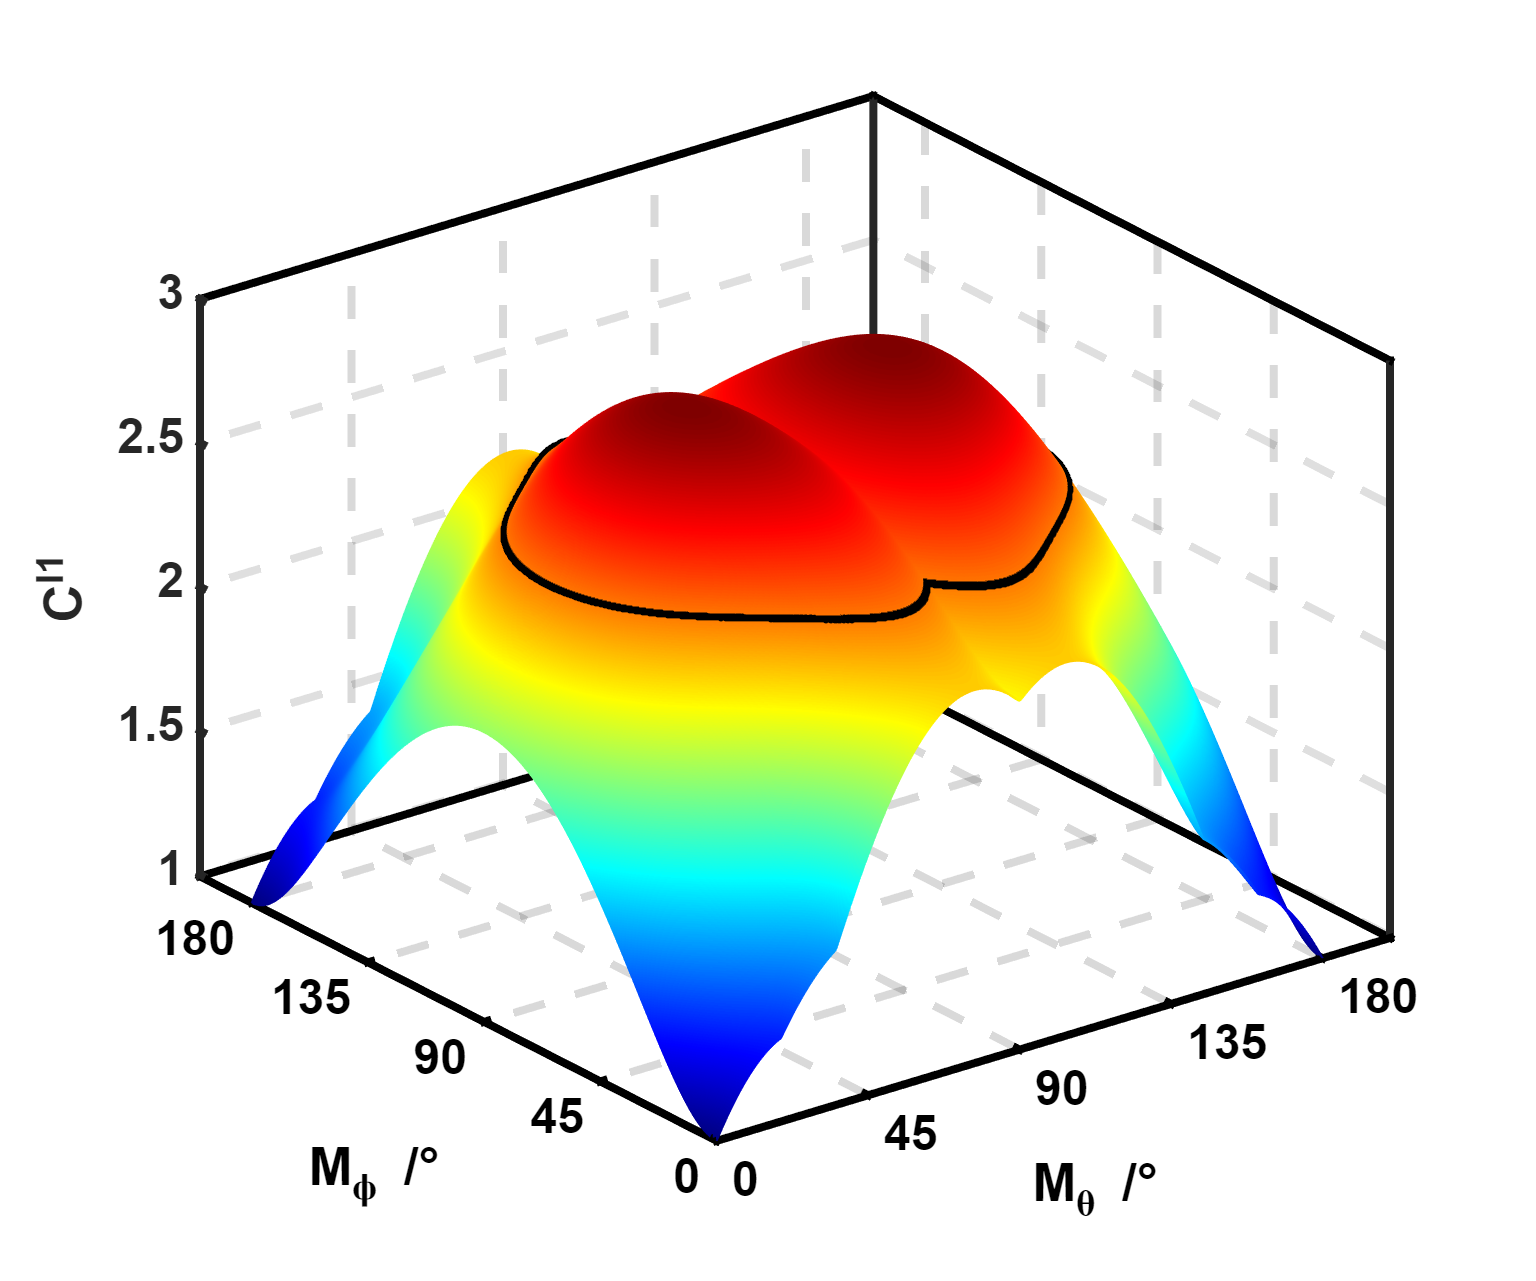

clc;
clear;
close all;

w_phi = 145;
w_theta = 60;
x = sind(w_theta)*cosd(w_phi);
y = sind(w_theta)*sind(w_phi);
z = cosd(w_theta);
H = [1,0]';
V = [0,1]';
W = x*kron(kron(V,H),H)+y*kron(kron(H,V),H)+z*kron(kron(H,H),V);
rho = W*W';

Theta = linspace(0,pi,1000);
Phi = linspace(0,pi,1000);
Cl1 = zeros(length(Theta),length(Phi));

for index_theta = 1:length(Theta)
    theta_1 = Theta(index_theta);
    for index_phi = 1:length(Phi)
        phi_1 = Phi(index_phi);
        Cl1(index_theta,index_phi) = inequality4(rho,theta_1,phi_1);
    end
    theta_1;
end

[T,P] = meshgrid(Theta,Phi);
k = mesh(T/pi*180,P/pi*180,real(Cl1'));
colormap('jet'); 
r0 = (abs(Cl1'-sqrt(6))<=0.01);
zz = r0.*sqrt(6);
yy = r0.*P/pi*180;
xx = r0.*T/pi*180;
hold on
scatter3(xx(r0~=0),yy(r0~=0),zz(r0~=0),3,'k','filled','o')

xlabel('M_\theta /°');
ylabel('M_\phi /°');
zlabel('C^{l1}');
g = get(k,'Parent');
set(g,'LineWidth',2);
set(gca, 'Box', 'on', ...
    'XGrid', 'on', 'YGrid', 'on', 'GridLineStyle','--',...
    'TickDir', 'in', 'TickLength', [.005 .005], ...
    'XMinorTick', 'off', 'YMinorTick', 'off', ...
    'XTick', 0:45:180,... 
    'YTick', 0:45:180,... 
    'XColor', [0 0 0],  'YColor', [0 0 0 ]);
set(gca, 'FontName', 'Helvetica', 'FontSize', 12,'FontWeight','bold');

set(gcf,'unit','normalized','position',[0.2,0.2,0.3,0.4]);